# Chapter 6 ATAP Exercises

## Weierstrass Approximation Theorem

#### Mason Mault June 2025

Worked Exercises

Exercise 6.1: A pathological function of Weierstrass

Exercise 6.3: Resolving a difficult function

**Exercise 6.1: A pathological function of Weierstrass**

Construct w7, a chebfun corresponding to the following series truncated at k = 7


$$w\left(x\right)=\sum_{k=0}^{\infty } 2^{-k} \cos \left(3^k x\right)$$


x1 = chebfun('x');

% first initialize w7 to the zero function
w7 = chebfun(0*x1);

for k = 0:7
    w7 = w7 + 2^(-k)*cos(3^k*x1);
end

Plot w7, its derivative, and its indefinite integral.

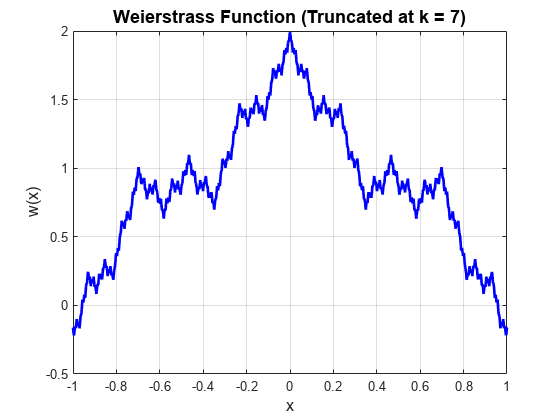

derw7 = diff(w7);
intw7 = cumsum(w7);

figure
plot(x1, w7, 'b', 'LineWidth', 2)
grid on

title('Weierstrass Function (Truncated at k = 7)', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('w(x)', 'FontSize', 12)

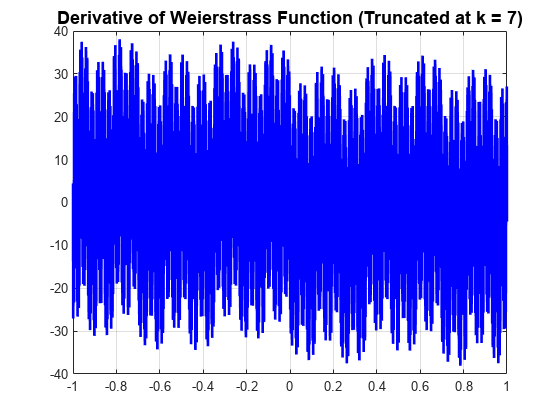

figure
plot(x1, derw7, 'b', 'LineWidth', 2)
grid on

title('Derivative of Weierstrass Function (Truncated at k = 7)', 'FontSize', 14, 'FontWeight', 'bold')

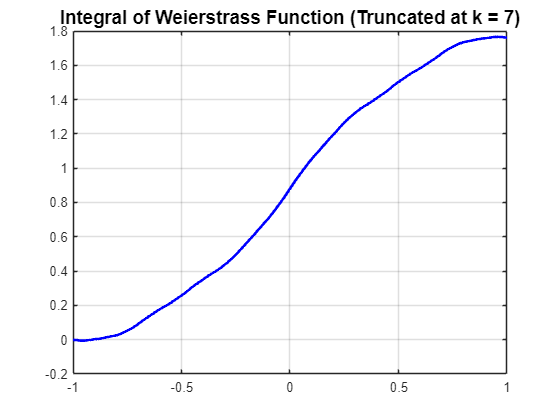

figure
plot(x1, intw7, 'b', 'LineWidth', 2)
grid on

title('Integral of Weierstrass Function (Truncated at k = 7)', 'FontSize', 14, 'FontWeight', 'bold')

The degree of polynomial defining the chebfun is

length(w7)

ans = 2315

**Exercise 6.3: Resolving a difficult function**

Although $f\left(x\right)=\sin \left(\frac{1}{x}\right)\sin \left(\frac{1}{\sin \left(\frac{1}{x}\right)}\right)$ is not Lipschitz continuous, its Chebyshev interpolants do converge. Explore the interpolation error as a function of n.

% define given interval and chebfun
a = 0.07;
b = 0.4;

f = chebfun(@(x) sin(1/x)*sin(1/sin(1/x)), [a, b], 1e5);

% initialization
% build list from 2^2 to 2^14 (change 14 to test convergence)
list = 2.^(2:20);
err = zeros(length(list), 1);

% compute chebfun interpolation and error at each value of list
for j = 1:length(list)
    i = list(j);
    n = i - 1;
    g = chebfun(f, i);
    % build and measure error on grid of 2n points
    x = chebpts(2*n, [a, b]);
    err(j) = norm(g(x) - f(x), inf);
end

Plot the function

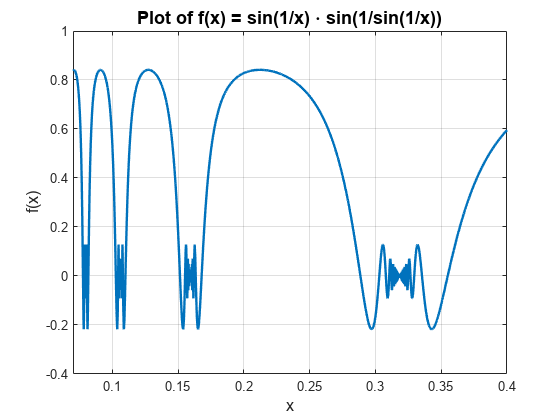

figure
plot(f, 'LineWidth', 1.8) 
grid on
title('Plot of f(x) = sin(1/x) \cdot sin(1/sin(1/x))', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)

Plot the error vs n on a loglog scale

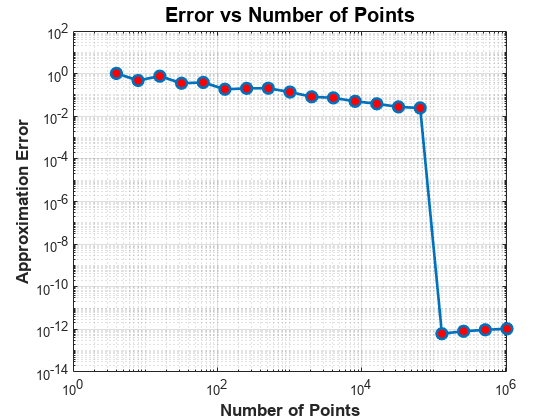

figure
loglog(list, err, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'Color', [0 0.4470 0.7410]);
grid on

xlabel('Number of Points', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Approximation Error', 'FontSize', 13, 'FontWeight', 'bold');
title('Error vs Number of Points', 'FontSize', 15, 'FontWeight', 'bold');

The error is rather stable until roughly n = 10^5, where the error drops rapidly. Trefethen provides a similar plot on page 19, explaining that up to a certain point, the interpolants wavenumbers are too small and the approximation can not do a good job. A threshold is then crossed where the error decays rapidly, as demonstrated here as well.

I have extended the number of points as far as I can, but machine precision is never reached.